## plot

使用 plot(x,y) 绘制二维折线图，其中 x，y 为同大小向量

figure;
x = 0:0.01:10;
y = sin(x);
plot(x,y)

当 x 为向量，y为矩阵时，若 y 的列等于 x 的长度，以 x 为横坐标，y的行向量为纵坐标，曲线数为矩阵行数

figure;
x = 0:0.01:10;
y = [sin(x);cos(x);cos(x)+sin(x)];
plot(x,y)

当 x 为向量，y为矩阵时，若 y 的行等于 x 的长度，以 x 为横坐标，y的列向量为纵坐标，曲线数为矩阵行数

figure;
x = 0:0.01:10;
y = [sin(x);cos(x);cos(x)+sin(x)].';
plot(x,y)

当 x，y 为同型矩阵，以两矩阵对应列元素为横纵坐标，曲线数等于列数

figure;
x = [1:0.01:10;1:0.01:10;1:0.01:10].';
y = [sin(2*x(:,1)),sin(1.5*x(:,2)),cos(2*x(:,1))];
plot(x,y)

输入多个x，y对时按照不同的点数进行相应绘图

figure;
x1 = linspace(0,2*pi,10);
x2 = linspace(0,2*pi,20);
x3 = linspace(0,2*pi,100);
y1 = sin(x1);
y2 = sin(x2)+1;
y3 = sin(x3)+2;
plot(x1,y1,x2,y2,x3,y3)

含选项的 plot，使用plot(x,y,选项)

figure;
x1 = linspace(0,2*pi,10);
x2 = linspace(0,2*pi,20);
x3 = linspace(0,2*pi,100);
y1 = sin(x1);
y2 = sin(x2)+1;
y3 = sin(x3)+2;
plot(x1,y1,'sk:',x2,y2,'r--^',x3,y3,'b-.o')

## fplot

plot 一般采用等间隔采样，实际应用时，函数可能会在某一区间变化剧烈，此时使用 fplot，使用 fplot(f,lims,选项)

f 为函数句柄，lims 为 x 轴取值范围，默认为 [-5,5]

figure;
f = @(x)sin(1./x);
fplot(f,[0,0.2],'ob--')

可以使用参数方程进行 fplot 绘图，使用 fplot (fx,fy,tlims,选项)

figure;
fx = @(t)16*sin(t).^3;
fy = @(t)13*cos(t)-5*cos(2*t)-2*cos(3*t)-cos(4*t);
fplot(fx,fy,[0,2*pi],'or--')

## 对数坐标

使用 semilogx(x1,y1,选项,x2,y2,选项...) 以 x 轴为对数

figure;
x1 = 0.01:0.01:100;
y1 = 0.01*log10(x1);
f1 = figure('Name','x 对数','NumberTitle','off');
subplot(2,1,1);
plot(x1, y1, 'b--', 'LineWidth', 1.5);
title('线性坐标系: y = 0.01 \cdot log_{10}(x)', 'FontSize', 14);
xlabel('自然坐标轴 x', 'FontSize', 10);
ylabel('自然坐标轴 y', 'FontSize', 10);
grid on;
subplot(2,1,2);
semilogx(x1, y1, 'r-.', 'LineWidth', 1.5);
title('半对数坐标系 (x轴对数): y = 0.01 \cdot log_{10}(x)', 'FontSize', 14);
xlabel('对数坐标轴 x', 'FontSize', 10);
ylabel('自然坐标轴 y', 'FontSize', 10);
grid on;

使用 semilogy(x1,y1,选项,x2,y2,选项...) 以 y 轴为对数

figure;
x2 = 0:0.01:5;
y2 = 10*exp(x2);
f2 = figure('Name','y 对数','NumberTitle','off');
subplot(2,1,1);
plot(x2, y2, 'b--', 'LineWidth', 1.5);
title('线性坐标系: y = 10e^x', 'FontSize', 14);
xlabel('自然坐标轴 x', 'FontSize', 10);
ylabel('自然坐标轴 y', 'FontSize', 10);
grid on;
subplot(2,1,2);
semilogy(x2, y2, 'r-.', 'LineWidth', 1.5);
title('半对数坐标系 (y轴对数): y = 10e^x', 'FontSize', 14);
xlabel('自然坐标轴 x', 'FontSize', 10);
ylabel('对数坐标轴 y', 'FontSize', 10);
grid on;

使用 loglog(x1,y1,选项,x2,y2,选项...) 两轴都为对数

figure;
x3 = 1:0.1:100;
y3 = x3.^2;
f3 = figure('Name','双对数','NumberTitle','off');
subplot(2,1,1);
plot(x3,y3,'b--', 'LineWidth', 1.5);
title('线性坐标系: x^2', 'FontSize', 14);
xlabel('x', 'FontSize', 10);
ylabel('y = x^2', 'FontSize', 10);
grid on;
subplot(2,1,2);
loglog(x3,y3,'r-.', 'LineWidth', 1.5);
title('双对数坐标系: x^2', 'FontSize', 14);
xlabel('x', 'FontSize', 10);
ylabel('y = x^2', 'FontSize', 10);
grid on

## 极坐标

使用 polar(theta,rho,选项) 建立极坐标图，使用 rlim([rmin rmax]) 调整 rho 范围

figure;
theta = pi;
rho = 15;
figure;
polarplot(theta, rho, 'b^--', 'LineWidth', 2,'MarkerSize', 8, 'MarkerFaceColor', 'blue');
title('极坐标点: (π, 15)');
rlim([0 20]);

## 条形图

使用 bar(x,y) 绘制垂直条形图，x 的个数与 y 的列数一致

figure;
x = 1:10;
y = [fix((rand(1,10)+1)*10);fix((rand(1,10)+2)*10);fix((rand(1,10)+1)*10)];
bar(x,y);

使用 barh 绘制水平条形图

figure;
x = 1:10;
y = [fix((rand(1,10)+1)*10);fix((rand(1,10)+2)*10);fix((rand(1,10)+1)*10)];
barh(x,y);

使用 grouped 为簇族分组，stacked 为堆积分组

figure;
x = 1:10;
y = [fix((rand(1,10)+1)*10);fix((rand(1,10)+2)*10);fix((rand(1,10)+1)*10)];
bar(x,y,'grouped');
figure;
x = 1:10;
y = [fix((rand(1,10)+1)*10);fix((rand(1,10)+2)*10);fix((rand(1,10)+1)*10)];
bar(x,y,'stacked');

    使用 `'FaceColor' 调整填充颜色， 'EdgeColor' 调整边缘颜色，'LineWidth'调整边缘宽度`

y = [75 91 105 123.5 131 150 179 203 226 249 281.5];
bar(y,'FaceColor',[0 .5 .5],'EdgeColor',[0 .9 .9],'LineWidth',1.5)

指定 x 为字符量

figure;
x = ["Spring" "Summer" "Autumn" "Winter"];
y = [1 2 3 4];
bar(x,y);

## 直方图

使用 hist(y,x) ，y 为统计数据，x 为划分方式，x 为标量分为 x 组，默认为 10 组

figure;
y = [0 2 9 2 5 8 7 3 1 9 4 3 5 8 10 0 1 2 9 5 10];
hist(y)

x 为向量时，以每个 x 为中心值进行分组

figure;
x = -1:1:10;
y = [0 2 9 2 5 8 7 3 1 9 4 3 5 8 10 0 1 2 9 5 10];
hist(y,x);

使用 y 为多列矩阵时，图像分簇

figure;
x = -5:1:5;
y = randn(1000,3);
hist(y,x);

使用 `polarhistogram(theta,x) 创建极直方图，theta 为数据，x 为标量时分为 x 组，默认为 3 组`

figure;
theta = rand(1,1000)*100-1;
polarhistogram(theta,50);

## 饼图

使用 pie(x) 绘制饼图，x 为数据

figure;
x = [1 1 1 1];
pie(x)

使用 labels 给饼图添加说明

figure;
x = [1 1 1 1];
label = {'A','B','C','D'};
pie(x,label);

使用 %% 指定百分比标签格式

figure;
x = [1/3 2/3];
pie(x,'%.3f%%')

使用和小于 1 的数据创建部分饼图

figure;
x = [0.19 0.22 0.41];
pie(x)

使用 [] 指定偏移部分，1 为漂移，0 为不漂移

figure;
x = 1:5;
explode = [0,0,1,0,1];
pie(x,explode);

## 散点图

使用 scatter(x,y) 绘制散点图

figure;
x = linspace(0,3*pi,200);
y = cos(x) + rand(1,200);  
scatter(x,y);

使用 scatter(x,y,sz,c) 调整大小颜色，sz 为大小数组，c 为颜色数组，使用 'filled' 可以填充散点

x = linspace(0,3*pi,200);
y = cos(x) + rand(1,200);
sz = linspace(1,100,length(x));
c = linspace(1,10,length(x));
scatter(x,y,sz,c,'filled');

## 针状图

使用 stem(y) 绘制针状图，y 为数据

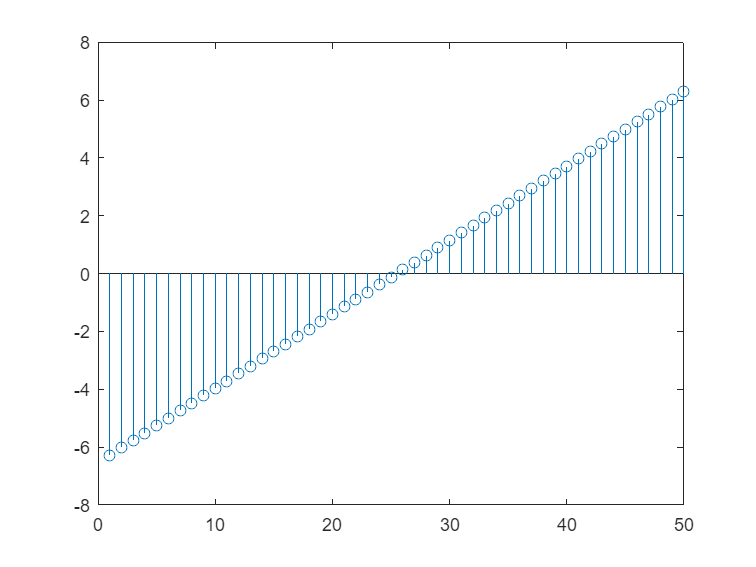

figure;
y = linspace(-2*pi,2*pi,50);
stem(y);

使用 [] 将数据括起，绘制多个数据的针状图

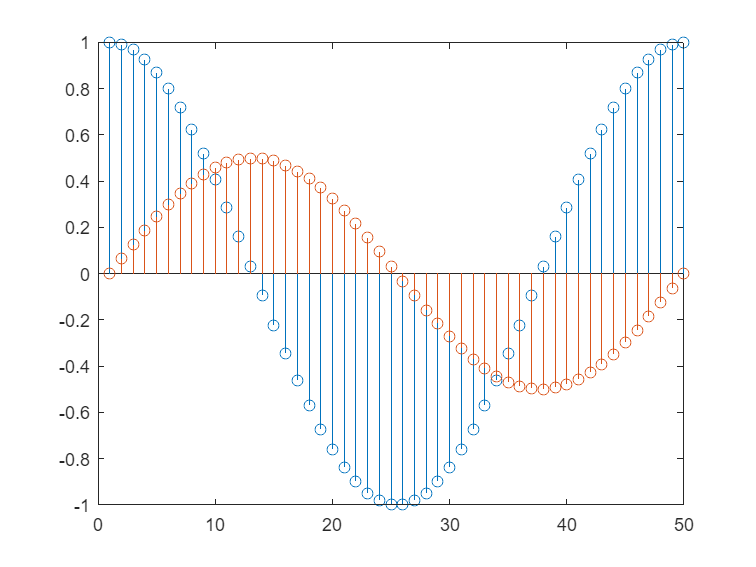

figure
x = linspace(0,2*pi,50)';
y = [cos(x), 0.5*sin(x)];
stem(y)

使用 stem(x,y) 在指定的位置绘制针状图

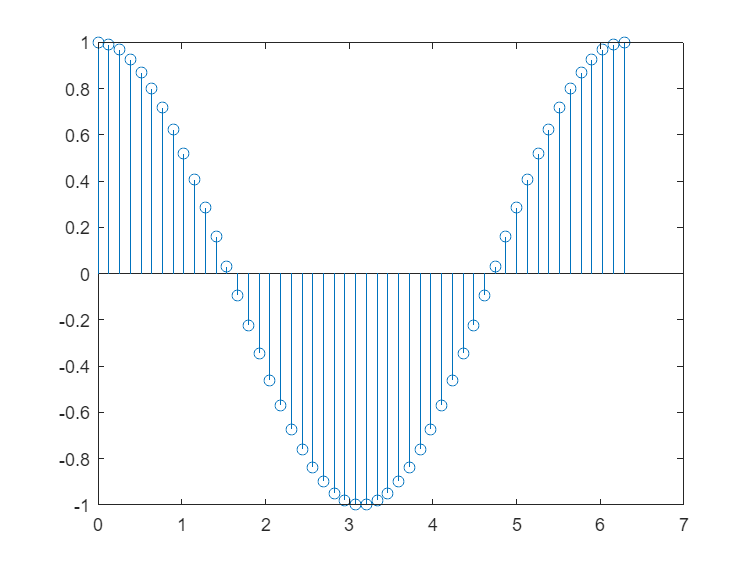

figure
x = linspace(0,2*pi,50)';
y = cos(x);
stem(x,y)

使用 [] 分别括起 x，y 后绘制不同位置的针状图

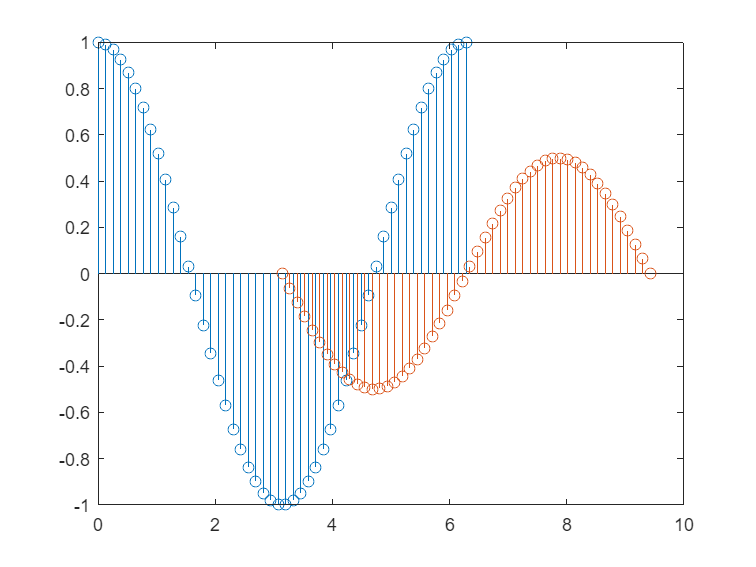

figure
x1 = linspace(0,2*pi,50)';
x2 = linspace(pi,3*pi,50)';
x = [x1, x2];
y = [cos(x1), 0.5*sin(x2)];
stem(x,y)